clear
clf
%1st problem (c)

a = 1.115 * 10^-3; %Thermal diffusivity(m^2/s)
u_o = 50;
u_L = 100;
u_od = 100;
u_Ld = 200;
L = 1; %Length of the domain (m)
x = linspace(0,1,1000);

%Steady state part
u_s = (((u_L - u_o)/L).*x) + u_o;

%Transient part
T = 0;
t = 0; %time (s)
for i = 1:100000
    b_1 = ((u_od-u_Ld)/(i*pi))*L*cos(i*pi);
    b_2 = ((L*u_od)/(i*pi))*(1 - cos(i*pi));
    b_3 = ((u_o-u_L)/(i*pi))*L*cos(i*pi);
    b_4 = ((L*u_o)/(i*pi))*(1 - cos(i*pi));
    b_n = (2/L)*(b_1 + b_2 - b_3 - b_4);
    e = exp((-a*t).*(((i.*pi)./L)^2));
    s = sin((i.*pi.*x)./L);
    T = T + (b_n.*e.*s);
end

%Total profile
U = T + u_s;

%Transient part
T_1 = 0;
t_1 = 10; %time (s)
for j = 1:100000
    b_1_1 = ((u_od-u_Ld)/(j*pi))*L*cos(j*pi);
    b_2_1 = ((L*u_od)/(j*pi))*(1 - cos(j*pi));
    b_3_1 = ((u_o-u_L)/(j*pi))*L*cos(j*pi);
    b_4_1 = ((L*u_o)/(j*pi))*(1 - cos(j*pi));
    b_n_1 = (2/L)*(b_1_1 + b_2_1 - b_3_1 - b_4_1);
    e_1 = exp((-a*t_1).*(((j.*pi)./L)^2));
    s_1 = sin((j.*pi.*x)./L);
    T_1 = T_1 + (b_n_1.*e_1.*s_1);
end

%Total profile
U_1 = T_1 + u_s;

%Transient part
T_2 = 0;
t_2 = 100; %time (s)
for k = 1:100000
    b_1_2 = ((u_od-u_Ld)/(k*pi))*L*cos(k*pi);
    b_2_2 = ((L*u_od)/(k*pi))*(1 - cos(k*pi));
    b_3_2 = ((u_o-u_L)/(k*pi))*L*cos(k*pi);
    b_4_2 = ((L*u_o)/(k*pi))*(1 - cos(k*pi));
    b_n_2 = (2/L)*(b_1_2 + b_2_2 - b_3_2 - b_4_2);
    e_2 = exp((-a*t_2).*(((k.*pi)./L)^2));
    s_2 = sin((k.*pi.*x)./L);
    T_2 = T_2 + (b_n_2.*e_2.*s_2);
end

%Total profile
U_2 = T_2 + u_s;

%Transient part
T_3 = 0;
t_3 = 1000; %time (s)
for l = 1:100000
    b_1_3 = ((u_od-u_Ld)/(l*pi))*L*cos(l*pi);
    b_2_3 = ((L*u_od)/(l*pi))*(1 - cos(l*pi));
    b_3_3 = ((u_o-u_L)/(l*pi))*L*cos(l*pi);
    b_4_3 = ((L*u_o)/(l*pi))*(1 - cos(l*pi));
    b_n_3 = (2/L)*(b_1_3 + b_2_3 - b_3_3 - b_4_3);
    e_3 = exp((-a*t_3).*(((l.*pi)./L)^2));
    s_3 = sin((l.*pi.*x)./L);
    T_3 = T_3 + (b_n_3.*e_3.*s_3);
end

%Total profile
U_3 = T_3 + u_s;

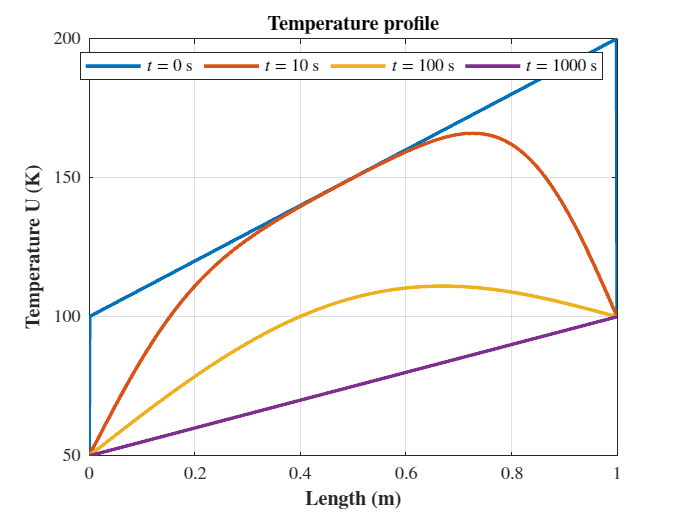

h1 = plot(x, U,'LineWidth', 2);
grid on
ylabel('$\textbf{Temperature U (K)}$','Interpreter', 'latex')
xlabel('$\textbf{Length (m)}$', 'Interpreter', 'latex')
title('$\textbf{Temperature profile}$', 'Interpreter', 'latex');
hold on
h2 = plot(x, U_1,'LineWidth', 2);
h3 = plot(x, U_2,'LineWidth',2);
h4 = plot(x, U_3,'LineWidth',2);
legend([h1, h2, h3, h4], '$t = 0$ s', '$t = 10$ s', '$t = 100$ s','$t = 1000$ s', 'Orientation', 'horizontal', 'Interpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex');

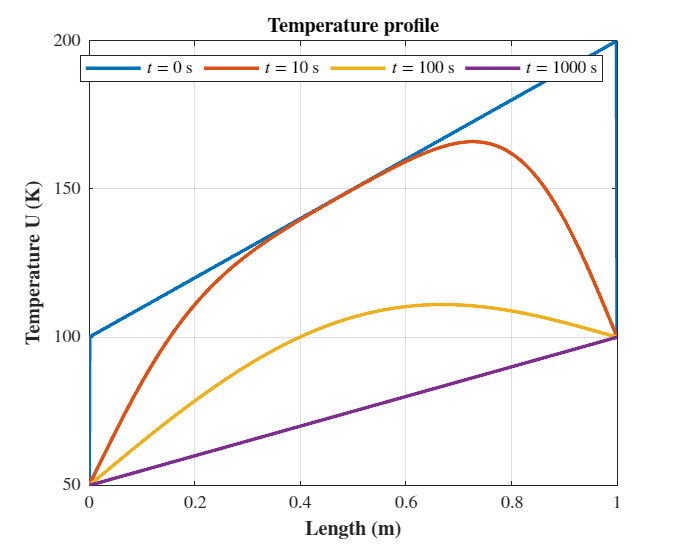

%Saving plot
outputFileName = 'Problem_1_c.png';
figureHandle = gcf;
figureWidth = 1000; % in pixels
figureHeight = 800; % in pixels
set(figureHandle, 'Position', [100, 100, figureWidth, figureHeight]); 
print(figureHandle, outputFileName, '-dpng', '-r600');